# Analysis trajectory of multi bodyparts

clear; close all;

## Load TrajGroupClass file

[TrajGroupFileName, TrajGroupFolder] = uigetfile("F:\YuLab\Work\GPS\Video\*.mat");
if ~TrajGroupFileName
    return
end
TrajGroupFilePath = fullfile(TrajGroupFolder, TrajGroupFileName);

load(TrajGroupFilePath);

FigFolder = fullfile(TrajGroupFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

## Calculate distance matrix

Features = [
    ["AngleHead" "PosXHead" "PosYHead"];...
    ["AngSpeedHead" "SpeedXHead" "SpeedYHead"]
    ];
FeatureLabels = [
    ["Head angle (°)" "Head x position (px)" "Head y position (px)"]; ...
    ["Head ang. speed (°/ms)" "Head x speed (px/ms)" "Head y speed (px/ms)"]
    ];

TraceGathered = obj.gatherTrace(Features(:));

MatWarpAlign = obj.trace2mat(TraceGathered, obj.TimeWarped, obj.TimeWarpAlign);
TraceWarpAlign = obj.mat2trace(MatWarpAlign, obj.TimeWarpAlign);

obj.DistMatLw = obj.calDist(TraceWarpAlign);

10731 / 1073112    - 1%
21462 / 1073112    - 2%
32193 / 1073112    - 3%
42924 / 1073112    - 4%
53655 / 1073112    - 5%
64386 / 1073112    - 6%
75117 / 1073112    - 7%
85848 / 1073112    - 8%
96579 / 1073112    - 9%
107310 / 1073112    - 10%
118041 / 1073112    - 11%
128772 / 1073112    - 12%
139503 / 1073112    - 13%
150234 / 1073112    - 14%
160965 / 1073112    - 15%
171696 / 1073112    - 16%
182427 / 1073112    - 17%
193158 / 1073112    - 18%
203889 / 1073112    - 19%
214620 / 1073112    - 20%
225351 / 1073112    - 21%
236082 / 1073112    - 22%
246813 / 1073112    - 23%
257544 / 1073112    - 24%
268275 / 1073112    - 25%
279006 / 1073112    - 26%
289737 / 1073112    - 27%
300468 / 1073112    - 28%
311199 / 1073112    - 29%
321930 / 1073112    - 30%
332661 / 1073112    - 31%
343392 / 1073112    - 32%
354123 / 1073112    - 33%
364854 / 1073112    - 34%
375585 / 1073112    - 35%
386316 / 1073112    - 36%
397047 / 1073112    - 37%
407778 / 1073112    - 38%
418509 / 1073112    - 39%
4292

obj.save(TrajGroupFolder);


## remove outliers

Info = obj.TrialInfo;

trials = find(Info.Cued==0 & Info.HD>0.5);
dists = sum(obj.DistMatLw(trials, trials), 2) / (length(trials)-1);

[~, ~, ind_rmv] = rmoutliers_custome(dists);
trials_rmv = trials(ind_rmv);
trials(ind_rmv) = [];

## Extract information

Info = obj.TrialInfo;

opts.trial_ctrl = cell(1, 2);
opts.num_ctrl = zeros(1, 2);
opts.color_ctrl = cell(1, 2);
opts.session_ctrl = cell(1, 2);
opts.session_date_ctrl = cell(1, 2);
opts.session_num_ctrl = cell(1, 2);
opts.session_sep_ctrl = cell(1, 2);

opts.trial_chemo = cell(1, 2);
opts.num_chemo = zeros(1, 2);
opts.color_chemo = cell(1, 2);
opts.session_chemo = cell(1, 2);
opts.session_date_chemo = cell(1, 2);
opts.session_num_chemo = cell(1, 2);
opts.session_sep_chemo = cell(1, 2);

for p = 1:2

    opts.trial_ctrl{p} = find(Info.Label=="Control" & Info.Cued==0 & Info.PortCorrect==obj.Ports(p) & Info.HD>0.5);
    opts.trial_ctrl{p} = setdiff(opts.trial_ctrl{p}, trials_rmv);
    opts.num_ctrl(p) = length(opts.trial_ctrl{p});
    opts.color_ctrl{p} = repmat(GPSColor.Control, opts.num_ctrl(p), 1);
    opts.session_ctrl{p} = Info.Session(opts.trial_ctrl{p});
    opts.session_date_ctrl{p} = unique(opts.session_ctrl{p});
    opts.session_num_ctrl{p} = zeros(length(opts.session_date_ctrl), 1);
    for k = 1:length(opts.session_date_ctrl{p})
        opts.session_num_ctrl{p}(k) = sum(opts.session_ctrl{p}==opts.session_date_ctrl{p}(k));
    end
    opts.session_sep_ctrl{p} = cumsum(opts.session_num_ctrl{p});

    opts.trial_chemo{p} = find(Info.Label=="Chemo" & Info.Cued==0 & Info.PortCorrect==obj.Ports(p) & Info.HD>0.5);
    opts.trial_chemo{p} = setdiff(opts.trial_chemo{p}, trials_rmv);
    opts.num_chemo(p) = length(opts.trial_chemo{p});
    opts.color_chemo{p} = repmat(GPSColor.Treat, opts.num_chemo(p), 1);
    opts.session_chemo{p} = Info.Session(opts.trial_chemo{p});
    opts.session_date_chemo{p} = unique(opts.session_chemo{p});
    opts.session_num_chemo{p} = zeros(length(opts.session_date_chemo), 1);
    for k = 1:length(opts.session_date_chemo{p})
        opts.session_num_chemo{p}(k) = sum(opts.session_chemo{p}==opts.session_date_chemo{p}(k));
    end
    opts.session_sep_chemo{p} = cumsum(opts.session_num_chemo{p});

end

opts.trial = cellfun(@(x, y) [x; y], opts.trial_ctrl, opts.trial_chemo, 'UniformOutput', false);
opts.num_trial = opts.num_ctrl + opts.num_chemo;
opts.label = cell(1, 2);
for p = 1:2
    opts.label{p} = [zeros(opts.num_ctrl(p), 1); ones(opts.num_chemo(p), 1)];
end
opts.color_trial = cellfun(@(x, y) [x; y], opts.color_ctrl, opts.color_chemo, 'UniformOutput', false);
opts.session_trial = cellfun(@(x, y) [x; y], opts.session_ctrl, opts.session_chemo, 'UniformOutput', false);
opts.session_date = cellfun(@(x, y) [x; y], opts.session_date_ctrl, opts.session_date_chemo, 'UniformOutput', false);
opts.session_num = cellfun(@(x, y) [x; y], opts.session_num_ctrl, opts.session_num_chemo, 'UniformOutput', false);
opts.session_sep = cellfun(@(x, y) [x; y], opts.session_sep_ctrl, opts.session_sep_chemo, 'UniformOutput', false);

opts.num_size = min([opts.num_ctrl opts.num_chemo]);
opts.num_show = min([100 opts.num_size]);


## correct trials

opts_c.trial_ctrl = cell(1, 2);
opts_c.num_ctrl = zeros(1, 2);
opts_c.color_ctrl = cell(1, 2);
opts_c.session_ctrl = cell(1, 2);
opts_c.session_date_ctrl = cell(1, 2);
opts_c.session_num_ctrl = cell(1, 2);
opts_c.session_sep_ctrl = cell(1, 2);

opts_c.trial_chemo = cell(1, 2);
opts_c.num_chemo = zeros(1, 2);
opts_c.color_chemo = cell(1, 2);
opts_c.session_chemo = cell(1, 2);
opts_c.session_date_chemo = cell(1, 2);
opts_c.session_num_chemo = cell(1, 2);
opts_c.session_sep_chemo = cell(1, 2);

for p = 1:2

    opts_c.trial_ctrl{p} = find(Info.Label=="Control" & Info.Cued==0 & Info.PortCorrect==obj.Ports(p) & Info.Performance=="Correct");
    opts_c.trial_ctrl{p} = setdiff(opts_c.trial_ctrl{p}, trials_rmv);
    opts_c.num_ctrl(p) = length(opts_c.trial_ctrl{p});
    opts_c.color_ctrl{p} = repmat(GPSColor.Control, opts_c.num_ctrl(p), 1);
    opts_c.session_ctrl{p} = Info.Session(opts_c.trial_ctrl{p});
    opts_c.session_date_ctrl{p} = unique(opts_c.session_ctrl{p});
    opts_c.session_num_ctrl{p} = zeros(length(opts_c.session_date_ctrl), 1);
    for k = 1:length(opts_c.session_date_ctrl{p})
        opts_c.session_num_ctrl{p}(k) = sum(opts_c.session_ctrl{p}==opts_c.session_date_ctrl{p}(k));
    end
    opts_c.session_sep_ctrl{p} = cumsum(opts_c.session_num_ctrl{p});

    opts_c.trial_chemo{p} = find(Info.Label=="Chemo" & Info.Cued==0 & Info.PortCorrect==obj.Ports(p) & Info.Performance=="Correct");
    opts_c.trial_chemo{p} = setdiff(opts_c.trial_chemo{p}, trials_rmv);
    opts_c.num_chemo(p) = length(opts_c.trial_chemo{p});
    opts_c.color_chemo{p} = repmat(GPSColor.Treat, opts_c.num_chemo(p), 1);
    opts_c.session_chemo{p} = Info.Session(opts_c.trial_chemo{p});
    opts_c.session_date_chemo{p} = unique(opts_c.session_chemo{p});
    opts_c.session_num_chemo{p} = zeros(length(opts_c.session_date_chemo), 1);
    for k = 1:length(opts_c.session_date_chemo{p})
        opts_c.session_num_chemo{p}(k) = sum(opts_c.session_chemo{p}==opts_c.session_date_chemo{p}(k));
    end
    opts_c.session_sep_chemo{p} = cumsum(opts_c.session_num_chemo{p});

end

opts_c.trial = cellfun(@(x, y) [x; y], opts_c.trial_ctrl, opts_c.trial_chemo, 'UniformOutput', false);
opts_c.num_trial = opts_c.num_ctrl + opts_c.num_chemo;
opts_c.label = cell(1, 2);
for p = 1:2
    opts_c.label{p} = [zeros(opts_c.num_ctrl(p), 1); ones(opts_c.num_chemo(p), 1)];
end
opts_c.color_trial = cellfun(@(x, y) [x; y], opts_c.color_ctrl, opts_c.color_chemo, 'UniformOutput', false);
opts_c.session_trial = cellfun(@(x, y) [x; y], opts_c.session_ctrl, opts_c.session_chemo, 'UniformOutput', false);
opts_c.session_date = cellfun(@(x, y) [x; y], opts_c.session_date_ctrl, opts_c.session_date_chemo, 'UniformOutput', false);
opts_c.session_num = cellfun(@(x, y) [x; y], opts_c.session_num_ctrl, opts_c.session_num_chemo, 'UniformOutput', false);
opts_c.session_sep = cellfun(@(x, y) [x; y], opts_c.session_sep_ctrl, opts_c.session_sep_chemo, 'UniformOutput', false);

opts_c.num_size = min([opts_c.num_ctrl opts_c.num_chemo]);
opts_c.num_show = min([100 opts_c.num_size]);



# Plot trace of features 

## aligned to poke-in

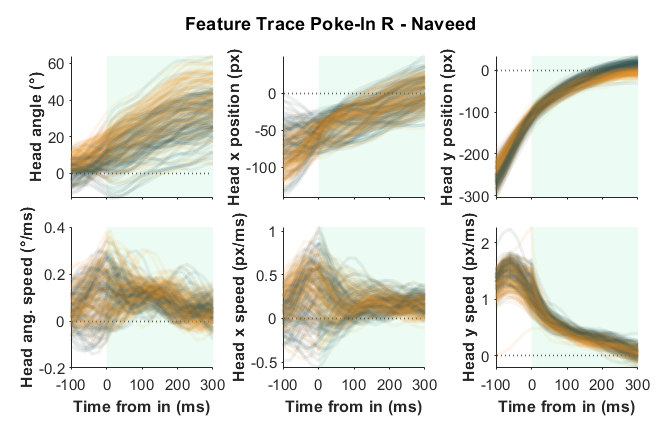

ax_w = 3; ax_h = 3;
ax_sep_w = 1.5; ax_sep_h = .6;

ax_pos = cell(size(Features));
for i = 1:size(Features, 1)
    for j = 1:size(Features, 2)
        ax_pos{i, j} = [1.5 + (j-1)*(ax_w+ax_sep_w) 1.2 + (size(Features, 1)-i)*(ax_h+ax_sep_h)];
    end
end

for p = 1:2
    fig_trace_in = figure(51); clf(51);
    set(fig_trace_in, 'Units', 'Centimeters', 'Position', [5 5 14 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'visible', 'on');

    set_fig_title(fig_trace_in, sprintf("Feature Trace Poke-In %s - %s", obj.Ports(p), obj.ANM));

    for f = 1:length(Features(:))
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{p}(randperm(opts.num_ctrl(p), opts.num_show)); opts.trial_chemo{p}(randperm(opts.num_chemo(p), opts.num_show))];
        j_color = [opts.color_ctrl{p}(1:opts.num_show, :); opts.color_chemo{p}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeFromIn{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

%         trace_control = obj.trace2mat(obj.(Features(f))(opts.trial_ctrl{p}), obj.TimeFromIn(opts.trial_ctrl{p}), obj.TimeMatIn);
%         plot(ax_front, obj.TimeMatIn, mean(trace_control, 1, 'omitnan'), 'Color', GPSColor.Control, 'LineWidth', 2);
% 
%         trace_chemo = obj.trace2mat(obj.(Features(f))(opts.trial_chemo{p}), obj.TimeFromIn(opts.trial_chemo{p}), obj.TimeMatIn);
%         plot(ax_front, obj.TimeMatIn, mean(trace_chemo, 1, 'omitnan'), 'Color', GPSColor.Treat, 'LineWidth', 2);

        ax_front.XLim = [-100 300];
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        if ~mod(f, 2)
            ax_front.XLabel.String = "Time from in (ms)";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, 1000*[0 obj.TaskFP obj.TaskFP 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
            'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

    end

    save_name = "FeatureTraceIn_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(1000*obj.TaskFP) + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    exportgraphics(fig_trace_in, save_path, 'Resolution', 600);
end

## Plot trace of features (aligned to poke-out)

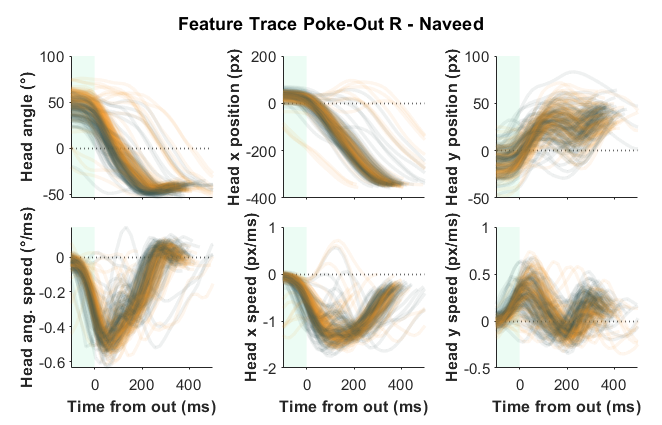

ax_w = 3; ax_h = 3;
ax_sep_w = 1.5; ax_sep_h = .6;

ax_pos = cell(size(Features));
for i = 1:size(Features, 1)
    for j = 1:size(Features, 2)
        ax_pos{i, j} = [1.5 + (j-1)*(ax_w+ax_sep_w) 1.2 + (size(Features, 1)-i)*(ax_h+ax_sep_h)];
    end
end

for p = 1:2
    fig_trace_out = figure(52); clf(52);
    set(fig_trace_out, 'Units', 'Centimeters', 'Position', [5 5 14 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'visible', 'on');

    set_fig_title(fig_trace_out, sprintf("Feature Trace Poke-Out %s - %s", obj.Ports(p), obj.ANM));

    for f = 1:length(Features(:))
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts_c.trial_ctrl{p}(randperm(opts_c.num_ctrl(p), opts_c.num_show)); opts_c.trial_chemo{p}(randperm(opts_c.num_chemo(p), opts_c.num_show))];
        j_color = [opts_c.color_ctrl{p}(1:opts_c.num_show, :); opts_c.color_chemo{p}(1:opts_c.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeFromOut{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = [-100 500];
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        if ~mod(f, 2)
            ax_front.XLabel.String = "Time from out (ms)";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, -1000*[0 obj.TaskFP obj.TaskFP 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
            'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

    end

    save_name = "FeatureTraceOut_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(1000*obj.TaskFP) + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    exportgraphics(fig_trace_out, save_path, 'Resolution', 600);
end

## Plot trace of features (warped)

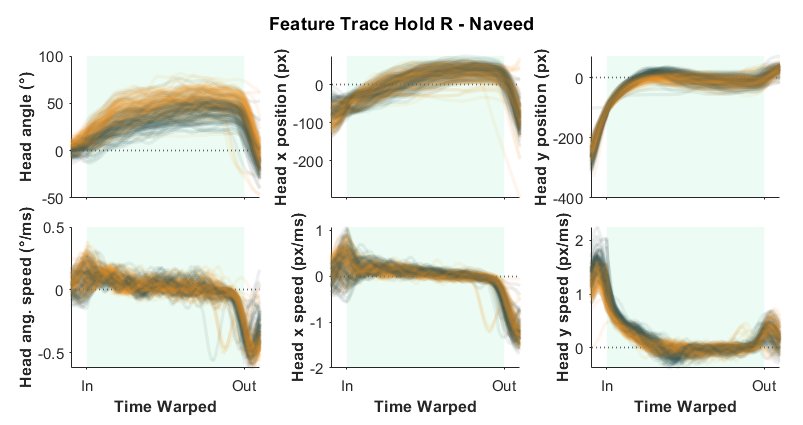

ax_w = 4; ax_h = 3;
ax_sep_w = 1.5; ax_sep_h = .6;

ax_pos = cell(size(Features));
for i = 1:size(Features, 1)
    for j = 1:size(Features, 2)
        ax_pos{i, j} = [1.5 + (j-1)*(ax_w+ax_sep_w) 1.2 + (size(Features, 1)-i)*(ax_h+ax_sep_h)];
    end
end

for p = 1:2
    fig_trace_warp = figure(53); clf(53);
    set(fig_trace_warp, 'Units', 'Centimeters', 'Position', [5 5 17 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'visible', 'on');

    set_fig_title(fig_trace_warp, sprintf("Feature Trace Hold %s - %s", obj.Ports(p), obj.ANM));

    for f = 1:length(Features(:))
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{p}(randperm(opts.num_ctrl(p), opts.num_show)); opts.trial_chemo{p}(randperm(opts.num_chemo(p), opts.num_show))];
        j_color = [opts.color_ctrl{p}(1:opts.num_show, :); opts.color_chemo{p}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeWarped{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = [-.1 1.1];
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        ax_front.XTick = [0 1];
        ax_front.XTickLabel = ["In" "Out"];

        if ~mod(f, 2)
            ax_front.XLabel.String = "Time Warped";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, [0 1 1 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
            'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

    end

    save_name = "FeatureTraceWarped_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(1000*obj.TaskFP) + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    exportgraphics(fig_trace_warp, save_path, 'Resolution', 600);
end

## Plot speed of head

v_Hold = cellfun(@(x, t1, t2) mean(x(t1>300 & t2<-100)), obj.SpeedHead, obj.TimeFromIn, obj.TimeFromOut)';

v_hold_control = cellfun(@(x) v_Hold(x), opts.trial_ctrl, 'UniformOutput', false);
v_hold_chemo = cellfun(@(x) v_Hold(x), opts.trial_chemo, 'UniformOutput', false);

v_hold_control_median = cellfun(@(x) median(x), v_hold_control);
v_hold_chemo_median = cellfun(@(x) median(x), v_hold_chemo);

bootci_medain = @(x) bootci(1000, @(y) median(y, "omitnan"), x);

v_hold_control_median_ci = cellfun(@(x) bootci_medain(x), v_hold_control, 'UniformOutput', false);
v_hold_chemo_median_ci = cellfun(@(x) bootci_medain(x), v_hold_chemo, 'UniformOutput', false);


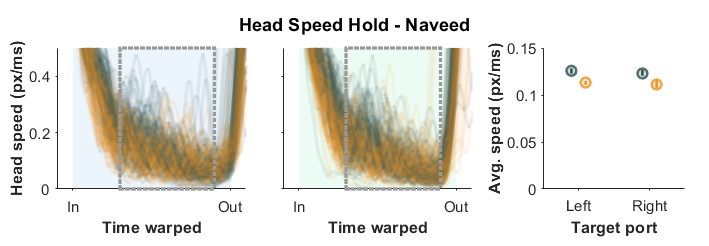

ax_size = [4 3];
ax_pos = {[1.2 1.2], [6 1.2], [11.5 1.2]};

fig_speed = figure(54); clf(54);
set(fig_speed, 'Units', 'Centimeters', 'Position', [5 5 15 5.2], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on');

set_fig_title(fig_speed, sprintf("Head Speed Hold - %s", obj.ANM));

for p = 1:2

    time_trace = obj.TimeWarped;
    time_mat = obj.TimeMatWarp;
    fill_area = [0 1 1 0];
    fill_color = GPSColor.("Port"+obj.Ports(p));
    x_label = 'Time warped';

    ax_back = axes;
    set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

    ax_front = axes;
    set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

    j_trials = [opts.trial_ctrl{p}(randperm(opts.num_ctrl(p), opts.num_show)); opts.trial_chemo{p}(randperm(opts.num_chemo(p), opts.num_show))];
    j_color = [opts.color_ctrl{p}(1:opts.num_show, :); opts.color_chemo{p}(1:opts.num_show, :)];
    j_shuffle = randperm(length(j_trials));

    for i = 1:length(j_trials)
        i_trial = j_trials(j_shuffle(i));
        i_color = j_color(j_shuffle(i), :);
        plot(ax_front, time_trace{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
    end

    ax_front.XLim = [-.1 1.1];
    ax_front.XTick = [0 1];
    ax_front.XTickLabel = ["In" "Out"];
    ax_front.YLim(2) = .5*(ceil(max(v_Hold(trials))) + round(max(v_Hold(trials))));

    ax_front.XLabel.String = x_label;
    ax_front.XLabel.FontWeight = "bold";
    switch p
        case 1
            ax_front.YLabel.String = "Head speed (px/ms)";
            ax_front.YLabel.FontWeight = "bold";
        case 2
            ax_front.YTickLabel = [];
    end
    
    fill(ax_front, [.3 .9 .9 .3], [ax_front.YLim(1) ax_front.YLim(1) ax_front.YLim(2) ax_front.YLim(2)], 'r', ...
        'FaceColor', 'none', 'FaceAlpha', .1, 'EdgeColor', [.6 .6 .6], 'LineStyle', ':', 'LineWidth', 2);

    ax_back.XLim = ax_front.XLim;
    ax_back.YLim = ax_front.YLim;
    fill(ax_back, fill_area, [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
        'FaceColor', fill_color, 'FaceAlpha', .1, 'EdgeColor', 'none');
    %         yline(ax_back, 0, ':', 'LineWidth', 1);
end

ax_stat = axes(fig_speed, 'Units', 'Centimeters', 'Position', [ax_pos{3} 3 3], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_stat, [1 2]-.1, v_hold_control_median, 36, GPSColor.Control, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .2, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
scatter(ax_stat, [1 2]+.1, v_hold_chemo_median, 36, GPSColor.Treat, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .2, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
for p=1:2
    plot(ax_stat, [p p]-.1, v_hold_control_median_ci{p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
    plot(ax_stat, [p p]+.1, v_hold_chemo_median_ci{p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
end
set(ax_stat, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["Left" "Right"], 'YLim', [0 0.15]);
ax_stat.YLim(1) = 0;
ax_stat.YLabel.String = "Avg. speed (px/ms)";
ax_stat.YLabel.FontWeight = "bold";
ax_stat.XLabel.String = "Target port";
ax_stat.XLabel.FontWeight = "bold";

save_name = "SpeedTraceHold_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
exportgraphics(fig_speed, save_path, 'Resolution', 600);

## approach

v_App = cellfun(@(x, t) mean(x(t<0)), obj.SpeedHead, obj.TimeFromIn)';

v_app_control = cellfun(@(x) v_App(x), opts.trial_ctrl, 'UniformOutput', false);
v_app_chemo = cellfun(@(x) v_App(x), opts.trial_chemo, 'UniformOutput', false);

v_app_control_median = cellfun(@(x) median(x), v_app_control);
v_app_chemo_median = cellfun(@(x) median(x), v_app_chemo);

bootci_medain = @(x) bootci(1000, @(y) median(y, "omitnan"), x);

v_app_control_median_ci = cellfun(@(x) bootci_medain(x), v_app_control, 'UniformOutput', false);
v_app_chemo_median_ci = cellfun(@(x) bootci_medain(x), v_app_chemo, 'UniformOutput', false);


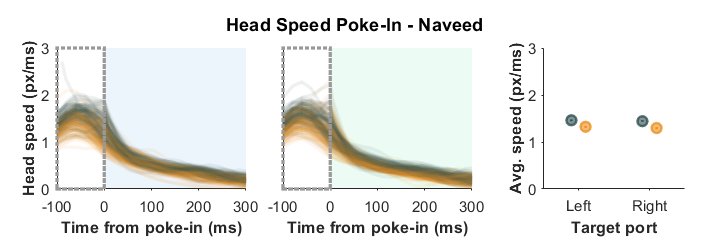

ax_size = [4 3];
ax_pos = {[1.2 1.2], [6 1.2], [11.5 1.2]};

fig_speed = figure(55); clf(55);
set(fig_speed, 'Units', 'Centimeters', 'Position', [5 5 15 5.2], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on');

set_fig_title(fig_speed, sprintf("Head Speed Poke-In - %s", obj.ANM));

for p = 1:2

    time_trace = obj.TimeFromIn;
    time_mat = obj.TimeMatIn;
    fill_area = 1000*[0 obj.TaskFP obj.TaskFP 0];
    fill_color = GPSColor.("Port"+obj.Ports(p));
    x_label = 'Time from poke-in (ms)';

    ax_back = axes;
    set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

    ax_front = axes;
    set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

    j_trials = [opts.trial_ctrl{p}(randperm(opts.num_ctrl(p), opts.num_show)); opts.trial_chemo{p}(randperm(opts.num_chemo(p), opts.num_show))];
    j_color = [opts.color_ctrl{p}(1:opts.num_show, :); opts.color_chemo{p}(1:opts.num_show, :)];
    j_shuffle = randperm(length(j_trials));

    for i = 1:length(j_trials)
        i_trial = j_trials(j_shuffle(i));
        i_color = j_color(j_shuffle(i), :);
        plot(ax_front, time_trace{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
    end

    ax_front.XLim = [-100 300];
    ax_front.YLim(2) = ceil(max(v_App(trials)));

    ax_front.XLabel.String = x_label;
    ax_front.XLabel.FontWeight = "bold";
    switch p
        case 1
            ax_front.YLabel.String = "Head speed (px/ms)";
            ax_front.YLabel.FontWeight = "bold";
        case 2
            ax_front.YTickLabel = [];
    end
    
    fill(ax_front, [-100 0 0 -100], [ax_front.YLim(1) ax_front.YLim(1) ax_front.YLim(2) ax_front.YLim(2)], 'r', ...
        'FaceColor', 'none', 'FaceAlpha', .1, 'EdgeColor', [.6 .6 .6], 'LineStyle', ':', 'LineWidth', 2);

    ax_back.XLim = ax_front.XLim;
    ax_back.YLim = ax_front.YLim;
    fill(ax_back, fill_area, [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
        'FaceColor', fill_color, 'FaceAlpha', .1, 'EdgeColor', 'none');
    %         yline(ax_back, 0, ':', 'LineWidth', 1);
end

ax_stat = axes(fig_speed, 'Units', 'Centimeters', 'Position', [ax_pos{3} 3 3], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_stat, [1 2]-.1, v_app_control_median, 36, GPSColor.Control, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
scatter(ax_stat, [1 2]+.1, v_app_chemo_median, 36, GPSColor.Treat, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
for p=1:2
    plot(ax_stat, [p p]-.1, v_app_control_median_ci{p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
    plot(ax_stat, [p p]+.1, v_app_chemo_median_ci{p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
end
set(ax_stat, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["Left" "Right"], 'YLim', [0 1.5]);
ax_stat.YLim = ax_front.YLim;
ax_stat.YLabel.String = "Avg. speed (px/ms)";
ax_stat.YLabel.FontWeight = "bold";
ax_stat.XLabel.String = "Target port";
ax_stat.XLabel.FontWeight = "bold";

save_name = "SpeedTrace_In_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
exportgraphics(fig_speed, save_path, 'Resolution', 600);

## Out

bootci_medain = @(x) bootci(1000, @(y) median(y, "omitnan"), x);

tSpeed = 0:10:500;
matSpeed = obj.trace2mat(obj.SpeedHead, obj.TimeFromOut, tSpeed);
[v_Out_max, v_Out_t] = max(matSpeed, [], 2);
v_Out_t = tSpeed(v_Out_t);
% [v_Out_max, v_Out_t] = cellfun(@(x, t) max(x(t>0)), obj.SpeedHead, obj.TimeFromOut);

v_out_t_control = cellfun(@(x) v_Out_t(x), opts_c.trial_ctrl, 'UniformOutput', false);
v_out_t_chemo = cellfun(@(x) v_Out_t(x), opts_c.trial_chemo, 'UniformOutput', false);
v_out_t_control_median = cellfun(@(x) median(x), v_out_t_control);
v_out_t_chemo_median = cellfun(@(x) median(x), v_out_t_chemo);
v_out_t_control_median_ci = cellfun(@(x) bootci_medain(x), v_out_t_control, 'UniformOutput', false);
v_out_t_chemo_median_ci = cellfun(@(x) bootci_medain(x), v_out_t_chemo, 'UniformOutput', false);

v_out_max_control = cellfun(@(x) v_Out_max(x), opts_c.trial_ctrl, 'UniformOutput', false);
v_out_max_chemo = cellfun(@(x) v_Out_max(x), opts_c.trial_chemo, 'UniformOutput', false);
v_out_max_control_median = cellfun(@(x) median(x), v_out_max_control);
v_out_max_chemo_median = cellfun(@(x) median(x), v_out_max_chemo);
v_out_max_control_median_ci = cellfun(@(x) bootci_medain(x), v_out_max_control, 'UniformOutput', false);
v_out_max_chemo_median_ci = cellfun(@(x) bootci_medain(x), v_out_max_chemo, 'UniformOutput', false);


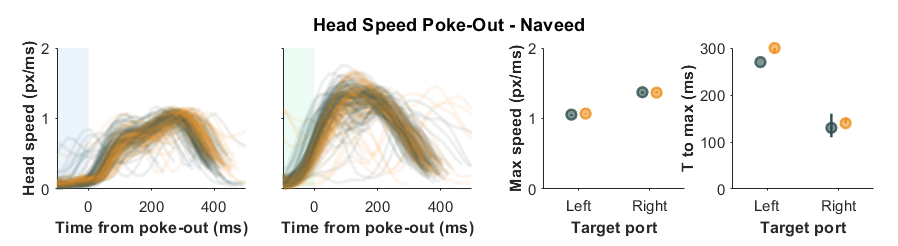

ax_size = [4 3];
ax_pos = {[1.2 1.2], [6 1.2], [11.5 1.2], [15.5 1.2]};

fig_speed = figure(56); clf(56);
set(fig_speed, 'Units', 'Centimeters', 'Position', [5 5 19 5.2], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on');

set_fig_title(fig_speed, sprintf("Head Speed Poke-Out - %s", obj.ANM));

for p = 1:2

    time_trace = obj.TimeFromOut;
    time_mat = obj.TimeMatOut;
    fill_area = -1000*[0 obj.TaskFP obj.TaskFP 0];
    fill_color = GPSColor.("Port"+obj.Ports(p));
    x_label = 'Time from poke-out (ms)';

    ax_back = axes;
    set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

    ax_front = axes;
    set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{p} ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

    j_trials = [opts_c.trial_ctrl{p}(randperm(opts_c.num_ctrl(p), opts_c.num_show)); opts_c.trial_chemo{p}(randperm(opts_c.num_chemo(p), opts_c.num_show))];
    j_color = [opts_c.color_ctrl{p}(1:opts_c.num_show, :); opts_c.color_chemo{p}(1:opts_c.num_show, :)];
    j_shuffle = randperm(length(j_trials));

    for i = 1:length(j_trials)
        i_trial = j_trials(j_shuffle(i));
        i_color = j_color(j_shuffle(i), :);
        plot(ax_front, time_trace{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
    end

    ax_front.XLim = [-100 500];
    ax_front.YLim(2) = .5*(ceil(max(v_Out_max(trials))) + round(max(v_Out_max(trials))));

    ax_front.XLabel.String = x_label;
    ax_front.XLabel.FontWeight = "bold";
    switch p
        case 1
            ax_front.YLabel.String = "Head speed (px/ms)";
            ax_front.YLabel.FontWeight = "bold";
        case 2
            ax_front.YTickLabel = [];
    end
%     
%     fill(ax_front, [300 0 0 300], [ax_front.YLim(1) ax_front.YLim(1) ax_front.YLim(2) ax_front.YLim(2)], 'r', ...
%         'FaceColor', 'none', 'FaceAlpha', .1, 'EdgeColor', [.6 .6 .6], 'LineStyle', ':', 'LineWidth', 2);

    ax_back.XLim = ax_front.XLim;
    ax_back.YLim = ax_front.YLim;
    fill(ax_back, fill_area, [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
        'FaceColor', fill_color, 'FaceAlpha', .1, 'EdgeColor', 'none');
    %         yline(ax_back, 0, ':', 'LineWidth', 1);
end

ax_stat = axes(fig_speed, 'Units', 'Centimeters', 'Position', [ax_pos{3} 3 3], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_stat, [1 2]-.1, v_out_max_control_median, 36, GPSColor.Control, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
scatter(ax_stat, [1 2]+.1, v_out_max_chemo_median, 36, GPSColor.Treat, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
for p=1:2
    plot(ax_stat, [p p]-.1, v_out_max_control_median_ci{p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
    plot(ax_stat, [p p]+.1, v_out_max_chemo_median_ci{p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
end
set(ax_stat, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["Left" "Right"]);
ax_stat.YLim = ax_front.YLim;
ax_stat.YLabel.String = "Max speed (px/ms)";
ax_stat.YLabel.FontWeight = "bold";
ax_stat.XLabel.String = "Target port";
ax_stat.XLabel.FontWeight = "bold";

ax_stat_2 = axes(fig_speed, 'Units', 'Centimeters', 'Position', [ax_pos{4} 3 3], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_stat_2, [1 2]-.1, v_out_t_control_median, 36, GPSColor.Control, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
scatter(ax_stat_2, [1 2]+.1, v_out_t_chemo_median, 36, GPSColor.Treat, 'filled', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, 'MarkerEdgeColor','flat', 'MarkerEdgeAlpha', .8, ...
    'LineWidth', 1.5);
for p=1:2
    plot(ax_stat_2, [p p]-.1, v_out_t_control_median_ci{p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
    plot(ax_stat_2, [p p]+.1, v_out_t_chemo_median_ci{p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
end
set(ax_stat_2, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["Left" "Right"]);
ax_stat_2.YLim(1) = 0;
ax_stat_2.YLabel.String = "T to max (ms)";
ax_stat_2.YLabel.FontWeight = "bold";
ax_stat_2.XLabel.String = "Target port";
ax_stat_2.XLabel.FontWeight = "bold";

save_name = "SpeedTraceOut_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
exportgraphics(fig_speed, save_path, 'Resolution', 600);

## Plot distance matrix

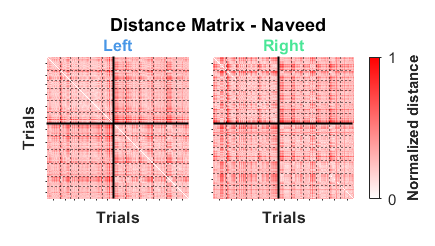

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

fig_dist = figure(57); clf(57);
set(fig_dist, 'Units', 'Centimeters', 'Position', [1 1 9.2 5.2], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on');

set_fig_title(fig_dist, sprintf("Distance Matrix - %s", obj.ANM));

for p = 1:2

    ax_dist = axes;
    set(ax_dist, 'Units', 'Centimeters', 'Position', [1+3.5*(p-1) 1 3 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');
    colormap(mycolormap);

    j_trials = [opts.trial_ctrl{p}; opts.trial_chemo{p}];
    j_DistM = obj.DistMatLw(opts.trial{p}, opts.trial{p});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(p), opts.num_trial(p));

    imagesc(j_DistM); clim([0 1]);

    j_seps = [opts.session_sep_ctrl{p}; opts.session_sep_ctrl{p}(end)+opts.session_sep_chemo{p}] + 0.5;

    xline(j_seps(1:end-1), 'LineStyle', ':', 'LineWidth', .6, 'Color', 'k', 'Alpha', 1);
    yline(j_seps(1:end-1), 'LineStyle', ':', 'LineWidth', .6, 'Color', 'k', 'Alpha', 1);

    xline(opts.num_ctrl(p)+0.5, 'LineStyle', '-', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
    yline(opts.num_ctrl(p)+0.5, 'LineStyle', '-', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

    xlim([.5 length(j_trials)+.5]);
    ylim([.5 length(j_trials)+.5]);

    xticks(j_seps - [opts.session_num_ctrl{p}; opts.session_num_chemo{p}] / 2); xticklabels([]);
    yticks(j_seps - [opts.session_num_ctrl{p}; opts.session_num_chemo{p}] / 2); yticklabels([]);

    if p == 1
        ax_dist.YLabel.String = "Trials";
        ax_dist.YLabel.FontWeight = "Bold";
    end
    ax_dist.XLabel.String = "Trials";
    ax_dist.XLabel.FontWeight = "Bold";

    switch p
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_dist, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');

end

cb = colorbar(ax_dist, 'Units', 'centimeters', 'Position', [7.8 1 .25 3], 'TickDirection', 'out', 'Ticks', [0 1]);
cb.FontSize = 9;
cb.Label.String = "Normalized distance";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';

save_name = "DistDtwMatrix_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
exportgraphics(fig_dist, save_path, 'Resolution', 600);

## MDS

% MDSScore = cell(1, 2);
% MDSCost  = cell(1, 2);
% 
% fig_mds = figure(56); clf(56);
% set(fig_mds, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
%     'string', "MDS Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% for p = 1:2
% 
%     j_DistM = obj.DistMatLw(opts.trial{p}, opts.trial{p});
%     j_DistM = normalize(j_DistM(:), 'range');
%     j_DistM = reshape(j_DistM, opts.num_trial(p), opts.num_trial(p));
% 
%     [MDSScore{p}, MDSCost{p}] = cmdscale(j_DistM);
%     
%     ax_mds = axes;
%     set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(p-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
% 
%     j_shuffle = randperm(opts.num_trial(p));
%     scatter(ax_mds, MDSScore{p}(j_shuffle,1), MDSScore{p}(j_shuffle,2), 32, opts.color_trial{p}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');
% 
%     if p == 1
%         ax_mds.YLabel.String = "MDS_2";
%         ax_mds.YLabel.FontWeight = "Bold";
%     end
%     ax_mds.XLabel.String = "MDS_1";
%     ax_mds.XLabel.FontWeight = "Bold";
% 
%     ax_mds.YLim = ax_mds.XLim;
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_mds, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% end
% 
% % save_name = "MDS_" + obj.ANM + "_" + obj.Task + ".jpg";
% % save_path = fullfile(FigFolder, save_name);
% % saveas(fig_mds, save_path);
% 

## t-SNE

% tSNEScore = cell(1, 2);
% 
% fig_tsne = figure(57); clf(57);
% set(fig_tsne, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_tsne, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
%     'string', "t-SNE Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% for p = 1:2
% 
%     j_DistM = obj.DistMatLw(opts.trial{p}, opts.trial{p});
%     j_DistM = normalize(j_DistM(:), 'range');
%     j_DistM = reshape(j_DistM, opts.num_trial(p), opts.num_trial(p));
% 
%     tSNEScore{p} = tsne_d(j_DistM);
%     
%     ax_tsne = axes;
%     set(ax_tsne, 'Units', 'Centimeters', 'Position', [2+8.5*(p-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
% 
%     j_shuffle = randperm(opts.num_trial(p));
%     scatter(ax_tsne, tSNEScore{p}(j_shuffle,1), tSNEScore{p}(j_shuffle,2), 32, opts.color_trial{p}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');
% 
%     if p == 1
%         ax_tsne.YLabel.String = "t-SNE_2";
%         ax_tsne.YLabel.FontWeight = "Bold";
%     end
%     ax_tsne.XLabel.String = "t-SNE_1";
%     ax_tsne.XLabel.FontWeight = "Bold";
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_tsne, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% end
% 
% save_name = "tSNE_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_tsne, save_path);
% 

# Predict hold phase using movement features

## Entire holding period ([0 1])

### loss function

% r_square = @(y, y_fit, ~) 1 - sum((y-y_fit).^2)/sum((y-mean(y)).^2);
% var_explained = @(y, y_fit, ~) 1 - var(y-y_fit)/var(y);
% 

### preprocess data

% time_bins = 0:0.05:1;
% TraceHold = cellfun(@(trace, t) trace(t>=0 & t<=1, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
% PhaseHold = cellfun(@(t) t(t>=0 & t<=1), obj.TimeWarped, 'UniformOutput', false);
% 
% ArrayHoldCtrl = cell(1, 2);
% ArrayHoldChemo = cell(1, 2);
% ArrayHoldCtrl_n = cell(1, 2);
% ArrayHoldChemo_n = cell(1, 2);
% 
% PhaseHoldCtrl = cell(1, 2);
% PhaseHoldChemo = cell(1, 2);
% 
% for p = 1:2
%     j_shuffle_ctrl = randperm(opts.num_ctrl(p), opts.num_size);
%     j_shuffle_chemo = randperm(opts.num_chemo(p), opts.num_size);
% 
%     ArrayHoldCtrl{p} = cell2mat(TraceHold(opts.trial_ctrl{p}(j_shuffle_ctrl))');
%     ArrayHoldChemo{p} = cell2mat(TraceHold(opts.trial_chemo{p}(j_shuffle_chemo))');
% 
%     ArrayHoldCtrl_n{p} = normalize(ArrayHoldCtrl{p}, 1, "range");
%     ArrayHoldChemo_n{p} = normalize(ArrayHoldChemo{p}, 1, "range");
% 
%     PhaseHoldCtrl{p} = cell2mat(PhaseHold(opts.trial_ctrl{p}(j_shuffle_ctrl))');
%     PhaseHoldChemo{p} = cell2mat(PhaseHold(opts.trial_chemo{p}(j_shuffle_chemo))');
% end
% 

### Linear model

% 
% MdlHoldCtrl_linear = cell(1, 2);
% MdlHoldChemo_linear = cell(1, 2);
% 
% fig_linear = figure(58); clf(58);
% set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
%     'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% 
% for p = 1:2
%     MdlHoldCtrl_linear{p} = fitrlinear(ArrayHoldCtrl_n{p}, PhaseHoldCtrl{p}, 'KFold', 10);
%     MdlHoldChemo_linear{p} = fitrlinear(ArrayHoldChemo_n{p}, PhaseHoldChemo{p}, 'KFold', 10);
% 
%     ax_ctrl = axes;
%     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_ctrl = kfoldPredict(MdlHoldCtrl_linear{p});
%     %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
%     y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_linear{p}.Y, y_fit_ctrl, time_bins, time_bins);
%     y_fit_ctrl_prob = y_fit_ctrl_prob';
%     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% 
%     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% 
%     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_ctrl.YLim = ax_ctrl.XLim;
%     ax_ctrl.XTick = 0:5:20;
%     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
%     ax_ctrl.YTick = ax_ctrl.XTick;
%     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% 
%     ax_chemo = axes;
%     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_chemo = kfoldPredict(MdlHoldChemo_linear{p});
%     y_fit_chemo_prob = histcounts2(MdlHoldChemo_linear{p}.Y, y_fit_chemo, time_bins, time_bins);
%     y_fit_chemo_prob = y_fit_chemo_prob';
%     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% 
%     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% 
%     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_chemo.YLim = ax_chemo.XLim;
%     ax_chemo.XTick = 0:5:20;
%     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
%     ax_chemo.YTick = ax_chemo.XTick;
%     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% 
%     ax_chemo.XLabel.String = "Hold phase";
%     ax_chemo.XLabel.FontWeight = "bold";
% 
%     if p == 2
%         cb.Label.String = "Predict probability";
%         cb.Label.FontSize = 11;
%         cb.Label.FontWeight = "bold";
%     end
% 
%     if p == 1
%         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
%         ax_ctrl.YLabel.FontWeight = "bold";
%         ax_ctrl.YLabel.Color = GPSColor.Control;
%         ax_chemo.YLabel.String = "Predicted phase Chemo";
%         ax_chemo.YLabel.FontWeight = "bold";
%         ax_chemo.YLabel.Color = GPSColor.Treat;
%     end
% end
% 
% save_name = "MdlHold_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_linear, save_path);
% 

### Neural network model

% % MdlHoldCtrl_nn = cell(1, 2);
% % MdlHoldChemo_nn = cell(1, 2);
% % 
% % fig_nn = figure(60); clf(60);
% % set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% % uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
% %     'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% % 
% % mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% % 
% % for p = 1:2
% %     MdlHoldCtrl_nn{p} = fitrnet(ArrayHoldCtrl_n{p}, PhaseHoldCtrl{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% %     MdlHoldChemo_nn{p} = fitrnet(ArrayHoldChemo_n{p}, PhaseHoldChemo{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% % 
% %     ax_ctrl = axes;
% %     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
% %     colormap(mycolormap);
% % 
% %     y_fit_ctrl = kfoldPredict(MdlHoldCtrl_nn{p});
% %     %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
% %     y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_nn{p}.Y, y_fit_ctrl, time_bins, time_bins);
% %     y_fit_ctrl_prob = y_fit_ctrl_prob';
% %     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% % 
% %     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% % 
% %     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
% %     ax_ctrl.YLim = ax_ctrl.XLim;
% %     ax_ctrl.XTick = 0:5:20;
% %     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
% %     ax_ctrl.YTick = ax_ctrl.XTick;
% %     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% % 
% %     switch p
% %         case 1
% %             title_text = "Left";
% %         case 2
% %             title_text = "Right";
% %     end
% %     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% % 
% %     ax_chemo = axes;
% %     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
% %     colormap(mycolormap);
% % 
% %     y_fit_chemo = kfoldPredict(MdlHoldChemo_nn{p});
% %     y_fit_chemo_prob = histcounts2(MdlHoldChemo_nn{p}.Y, y_fit_chemo, time_bins, time_bins);
% %     y_fit_chemo_prob = y_fit_chemo_prob';
% %     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% % 
% %     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% % 
% %     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
% %     ax_chemo.YLim = ax_chemo.XLim;
% %     ax_chemo.XTick = 0:5:20;
% %     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
% %     ax_chemo.YTick = ax_chemo.XTick;
% %     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% % 
% %     ax_chemo.XLabel.String = "Hold phase";
% %     ax_chemo.XLabel.FontWeight = "bold";
% % 
% %     if p == 2
% %         cb.Label.String = "Predict probability";
% %         cb.Label.FontSize = 11;
% %         cb.Label.FontWeight = "bold";
% %     end
% % 
% %     if p == 1
% %         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
% %         ax_ctrl.YLabel.FontWeight = "bold";
% %         ax_ctrl.YLabel.Color = GPSColor.Control;
% %         ax_chemo.YLabel.String = "Predicted phase Chemo";
% %         ax_chemo.YLabel.FontWeight = "bold";
% %         ax_chemo.YLabel.Color = GPSColor.Treat;
% %     end
% % end
% % 
% % save_name = "MdlHold_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
% % save_path = fullfile(FigFolder, save_name);
% % saveas(fig_nn, save_path);
% 

## Trimmed holding period ([.1 .9])

### preprocess data

% TraceTrim = cellfun(@(trace, t) trace(t>=.1 & t<=.9, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
% PhaseTrim = cellfun(@(t) t(t>=.1 & t<=.9), obj.TimeWarped, 'UniformOutput', false);
% 
% ArrayTrimCtrl = cell(1, 2);
% ArrayTrimChemo = cell(1, 2);
% ArrayTrimCtrl_n = cell(1, 2);
% ArrayTrimChemo_n = cell(1, 2);
% 
% PhaseTrimCtrl = cell(1, 2);
% PhaseTrimChemo = cell(1, 2);
% 
% for p = 1:2
%     j_shuffle_ctrl = randperm(opts.num_ctrl(p), opts.num_size);
%     j_shuffle_chemo = randperm(opts.num_chemo(p), opts.num_size);
% 
%     ArrayTrimCtrl{p} = cell2mat(TraceTrim(opts.trial_ctrl{p}(j_shuffle_ctrl))');
%     ArrayTrimChemo{p} = cell2mat(TraceTrim(opts.trial_chemo{p}(j_shuffle_chemo))');
% 
%     ArrayTrimCtrl_n{p} = normalize(ArrayTrimCtrl{p}, 1, "range");
%     ArrayTrimChemo_n{p} = normalize(ArrayTrimChemo{p}, 1, "range");
% 
%     PhaseTrimCtrl{p} = cell2mat(PhaseTrim(opts.trial_ctrl{p}(j_shuffle_ctrl))');
%     PhaseTrimChemo{p} = cell2mat(PhaseTrim(opts.trial_chemo{p}(j_shuffle_chemo))');
% end
% 

### Linear model

% 
% MdlTrimCtrl_linear = cell(1, 2);
% MdlTrimChemo_linear = cell(1, 2);
% 
% fig_linear = figure(58); clf(58);
% set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
%     'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% 
% for p = 1:2
%     MdlTrimCtrl_linear{p} = fitrlinear(ArrayTrimCtrl_n{p}, PhaseTrimCtrl{p}, 'KFold', 10);
%     MdlTrimChemo_linear{p} = fitrlinear(ArrayTrimChemo_n{p}, PhaseTrimChemo{p}, 'KFold', 10);
% 
%     ax_ctrl = axes;
%     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_ctrl = kfoldPredict(MdlTrimCtrl_linear{p});
%     %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
%     y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_linear{p}.Y, y_fit_ctrl, time_bins, time_bins);
%     y_fit_ctrl_prob = y_fit_ctrl_prob';
%     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% 
%     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% 
%     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_ctrl.YLim = ax_ctrl.XLim;
%     ax_ctrl.XTick = 0:5:20;
%     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
%     ax_ctrl.YTick = ax_ctrl.XTick;
%     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% 
%     ax_chemo = axes;
%     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_chemo = kfoldPredict(MdlTrimChemo_linear{p});
%     y_fit_chemo_prob = histcounts2(MdlTrimChemo_linear{p}.Y, y_fit_chemo, time_bins, time_bins);
%     y_fit_chemo_prob = y_fit_chemo_prob';
%     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% 
%     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% 
%     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_chemo.YLim = ax_chemo.XLim;
%     ax_chemo.XTick = 0:5:20;
%     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
%     ax_chemo.YTick = ax_chemo.XTick;
%     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% 
%     ax_chemo.XLabel.String = "Hold phase";
%     ax_chemo.XLabel.FontWeight = "bold";
% 
%     if p == 2
%         cb.Label.String = "Predict probability";
%         cb.Label.FontSize = 11;
%         cb.Label.FontWeight = "bold";
%     end
% 
%     if p == 1
%         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
%         ax_ctrl.YLabel.FontWeight = "bold";
%         ax_ctrl.YLabel.Color = GPSColor.Control;
%         ax_chemo.YLabel.String = "Predicted phase Chemo";
%         ax_chemo.YLabel.FontWeight = "bold";
%         ax_chemo.YLabel.Color = GPSColor.Treat;
%     end
% end
% 
% save_name = "MdlTrim_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_linear, save_path);
% 

### Neural network model

% % MdlTrimCtrl_nn = cell(1, 2);
% % MdlTrimChemo_nn = cell(1, 2);
% % 
% % fig_nn = figure(60); clf(60);
% % set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% % uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
% %     'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% % 
% % mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% % 
% % for p = 1:2
% %     MdlTrimCtrl_nn{p} = fitrnet(ArrayTrimCtrl_n{p}, PhaseTrimCtrl{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% %     MdlTrimChemo_nn{p} = fitrnet(ArrayTrimChemo_n{p}, PhaseTrimChemo{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% % 
% %     ax_ctrl = axes;
% %     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
% %     colormap(mycolormap);
% % 
% %     y_fit_ctrl = kfoldPredict(MdlTrimCtrl_nn{p});
% %     %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
% %     y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_nn{p}.Y, y_fit_ctrl, time_bins, time_bins);
% %     y_fit_ctrl_prob = y_fit_ctrl_prob';
% %     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% % 
% %     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% % 
% %     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
% %     ax_ctrl.YLim = ax_ctrl.XLim;
% %     ax_ctrl.XTick = 0:5:20;
% %     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
% %     ax_ctrl.YTick = ax_ctrl.XTick;
% %     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% % 
% %     switch p
% %         case 1
% %             title_text = "Left";
% %         case 2
% %             title_text = "Right";
% %     end
% %     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% % 
% %     ax_chemo = axes;
% %     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
% %     colormap(mycolormap);
% % 
% %     y_fit_chemo = kfoldPredict(MdlTrimChemo_nn{p});
% %     y_fit_chemo_prob = histcounts2(MdlTrimChemo_nn{p}.Y, y_fit_chemo, time_bins, time_bins);
% %     y_fit_chemo_prob = y_fit_chemo_prob';
% %     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% % 
% %     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% % 
% %     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
% %     ax_chemo.YLim = ax_chemo.XLim;
% %     ax_chemo.XTick = 0:5:20;
% %     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
% %     ax_chemo.YTick = ax_chemo.XTick;
% %     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% % 
% %     ax_chemo.XLabel.String = "Hold phase";
% %     ax_chemo.XLabel.FontWeight = "bold";
% % 
% %     if p == 2
% %         cb.Label.String = "Predict probability";
% %         cb.Label.FontSize = 11;
% %         cb.Label.FontWeight = "bold";
% %     end
% % 
% %     if p == 1
% %         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
% %         ax_ctrl.YLabel.FontWeight = "bold";
% %         ax_ctrl.YLabel.Color = GPSColor.Control;
% %         ax_chemo.YLabel.String = "Predicted phase Chemo";
% %         ax_chemo.YLabel.FontWeight = "bold";
% %         ax_chemo.YLabel.Color = GPSColor.Treat;
% %     end
% % end
% % 
% % save_name = "MdlTrim_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
% % save_path = fullfile(FigFolder, save_name);
% % saveas(fig_nn, save_path);
% 